% Main script to generate comparative plots
clear all; close all;

%% Dane wejściowe
scs = 30;       % Fixed SCS [kHz]
T_total = 1000;  % Simulation time [ms]
k0_values = [0, 2, 4, 8, 16, 32]; % Scheduling delays to test
packet_freqs = [35, 50, 100, 2000]; % Packet frequencies [ms]

%% Główny wykres (pełny zakres)
figure;
subplot(2,1,1); % Pierwszy panel - widok pełny
hold on;

% Symulacja i rysowanie krzywych
colors = lines(length(packet_freqs));
for freq_idx = 1:length(packet_freqs)
    energy_gain = arrayfun(@(k0) cross_slot_scheduling_script(k0, scs, packet_freqs(freq_idx), T_total), k0_values);
    plot(k0_values, energy_gain, '-o', 'LineWidth', 2, 'MarkerSize', 8, 'Color', colors(freq_idx,:));
end

 OFDM symbol length 0.03568
 Slot duration 0.50
 Number of slots 2000.00
 Packet_frequency per how many slot 70.00
MICRO SLEEP
rest time  2000.00
Slot nr 1 bez PDSCH
Zużycie energii cross slot scheduling = 28.37, zużycie energi same slot scheduling 49.95
Slot nr 2 bez PDSCH
Zużycie energii cross slot scheduling = 56.73, zużycie energi same slot scheduling 99.90
Slot nr 3 bez PDSCH
Zużycie energii cross slot scheduling = 85.10, zużycie energi same slot scheduling 149.86
Slot nr 4 bez PDSCH
Zużycie energii cross slot scheduling = 113.46, zużycie energi same slot scheduling 199.81
Slot nr 5 bez PDSCH
Zużycie energii cross slot scheduling = 141.83, zużycie energi same slot scheduling 249.76
Slot nr 6 bez PDSCH
Zużycie energii cross slot scheduling = 170.19, zużycie energi same slot scheduling 299.71
Slot nr 7 bez PDSCH
Zużycie energii cross slot scheduling = 198.56, zużycie energi same slot scheduling 349.66
Slot nr 8 bez PDSCH
Zużycie energii cross slot scheduling = 226.92, zużycie energi


% Formatowanie głównego wykresu
title('Energy Gain vs. k0 (SCS=30 kHz) - Full View');
xlabel('Scheduling Delay (k0, slots)');
ylabel('Energy Gain (%)');
legend({'Packet Freq = 35 ms', 'Packet Freq = 50 ms', 'Packet Freq = 100 ms', 'no packets'}, 'Location', 'southwest');
grid on;
ylim([50 105]);

%% Wykres zbliżeniowy (55-60%)
subplot(2,1,2); % Drugi panel - zbliżenie
hold on;

for freq_idx = 1:length(packet_freqs)
    energy_gain = arrayfun(@(k0) cross_slot_scheduling_script(k0, scs, packet_freqs(freq_idx), T_total), k0_values);
    plot(k0_values(2:end), energy_gain(2:end), '-o', 'LineWidth', 2, 'MarkerSize', 10, 'Color', colors(freq_idx,:));
end

 OFDM symbol length 0.03568
 Slot duration 0.50
 Number of slots 2000.00
 Packet_frequency per how many slot 70.00
MICRO SLEEP
rest time  2000.00
Slot nr 1 bez PDSCH
Zużycie energii cross slot scheduling = 28.37, zużycie energi same slot scheduling 49.95
Slot nr 2 bez PDSCH
Zużycie energii cross slot scheduling = 56.73, zużycie energi same slot scheduling 99.90
Slot nr 3 bez PDSCH
Zużycie energii cross slot scheduling = 85.10, zużycie energi same slot scheduling 149.86
Slot nr 4 bez PDSCH
Zużycie energii cross slot scheduling = 113.46, zużycie energi same slot scheduling 199.81
Slot nr 5 bez PDSCH
Zużycie energii cross slot scheduling = 141.83, zużycie energi same slot scheduling 249.76
Slot nr 6 bez PDSCH
Zużycie energii cross slot scheduling = 170.19, zużycie energi same slot scheduling 299.71
Slot nr 7 bez PDSCH
Zużycie energii cross slot scheduling = 198.56, zużycie energi same slot scheduling 349.66
Slot nr 8 bez PDSCH
Zużycie energii cross slot scheduling = 226.92, zużycie energi

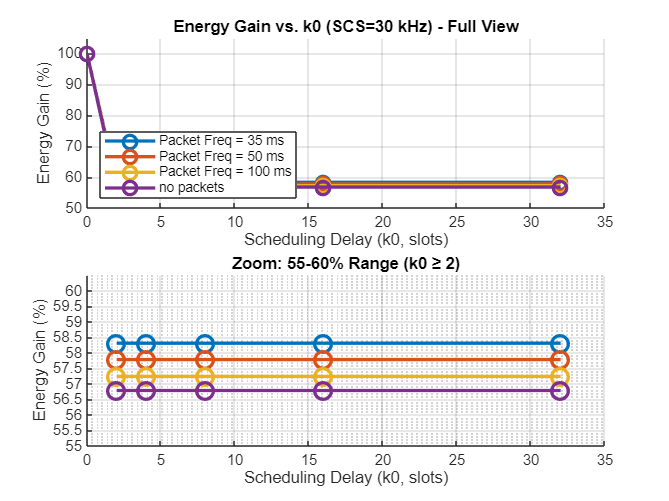


% Formatowanie zbliżenia
title('Zoom: 55-60% Range (k0 ≥ 2)');
xlabel('Scheduling Delay (k0, slots)');
ylabel('Energy Gain (%)');
grid on;
ylim([55 60.5]);
yticks(55:0.5:60);
set(gca, 'YMinorGrid', 'on');

%% 2. Energy vs. SCS with multiple packet frequencies
k0 = 2;          % Fixed cross-slot delay
T_total = 1000;   % Simulation time [ms]
scs_values = [15, 30, 60, 120]; % SCS options [kHz]
packet_freqs = [10, 25, 50, 100, 2000]; % Different packet frequencies to compare [ms]

% Custom legend labels
legend_labels = {
    'Packet Freq = 10 ms', 
    'Packet Freq = 25 ms', 
    'Packet Freq = 50 ms', 
    'Packet Freq = 100 ms', 
    'no packets'  % Changed from 'Packet Freq = 2000 ms'
};

figure;
hold on;

for freq_idx = 1:length(packet_freqs)
    energy_gain_scs = zeros(size(scs_values));
    for i = 1:length(scs_values)
        energy_gain_scs(i) = cross_slot_scheduling_script(k0, scs_values(i), packet_freqs(freq_idx), T_total);
    end
    plot(scs_values, energy_gain_scs, '-o', ...
        'LineWidth', 2, ...
        'DisplayName', legend_labels{freq_idx});
end

 OFDM symbol length 0.07136
 Slot duration 1.00
 Number of slots 1000.00
 Packet_frequency per how many slot 10.00
LIGHT SLEEP
rest time  1000.00
Slot nr 1 bez PDSCH
Zużycie energii cross slot scheduling = 47.75, zużycie energi same slot scheduling 99.90
Slot nr 2 bez PDSCH
Zużycie energii cross slot scheduling = 95.49, zużycie energi same slot scheduling 199.81
Slot nr 3 bez PDSCH
Zużycie energii cross slot scheduling = 143.24, zużycie energi same slot scheduling 299.71
Slot nr 4 bez PDSCH
Zużycie energii cross slot scheduling = 190.99, zużycie energi same slot scheduling 399.62
Slot nr 5 bez PDSCH
Zużycie energii cross slot scheduling = 238.74, zużycie energi same slot scheduling 499.52
Slot nr 6 bez PDSCH
Zużycie energii cross slot scheduling = 286.48, zużycie energi same slot scheduling 599.42
Slot nr 7 bez PDSCH
Zużycie energii cross slot scheduling = 334.23, zużycie energi same slot scheduling 699.33
Slot nr 8 bez PDSCH
Zużycie energii cross slot scheduling = 381.98, zużycie ener

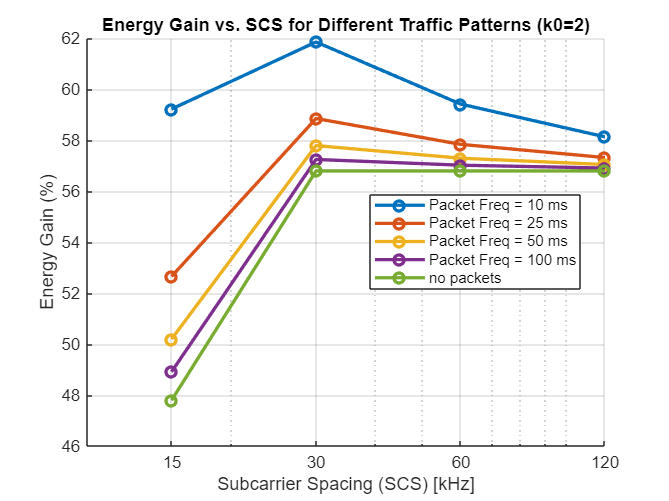


hold off;

% Formatting the plot
set(gca, 'XScale', 'log');
xlabel('Subcarrier Spacing (SCS) [kHz]');
ylabel('Energy Gain (%)');
title('Energy Gain vs. SCS for Different Traffic Patterns (k0=2)');  % Updated title
grid on;
xticks(scs_values);
legend('Location', 'best');

% %% 3. Energy vs. Packet Frequency for different SCS values
% k0 = 2;          % Fixed cross-slot delay
% T_total = 1000;   % Simulation time [ms]
% scs_values = [15, 30, 60, 120]; % SCS options [kHz]
% packet_freqs = [10, 25, 50, 100, 2000]; % Packet frequencies [ms]
% 
% colors = lines(length(scs_values)); % Get distinct colors
% 
% figure;
% hold on;
% 
% for scs_idx = 1:length(scs_values)
%     energy_gain_freq = zeros(size(packet_freqs));
%     for freq_idx = 1:length(packet_freqs)
%         energy_gain_freq(freq_idx) = cross_slot_scheduling_script(...
%             k0, scs_values(scs_idx), packet_freqs(freq_idx), T_total);
%     end
% 
%     plot(packet_freqs, energy_gain_freq, '-o', ...
%         'Color', colors(scs_idx,:), ...
%         'LineWidth', 2, ...
%         'DisplayName', sprintf('SCS = %d kHz', scs_values(scs_idx)));
% end
% 
% hold off;
% 
% % Formatting the plot
% xlabel('Packet Frequency [ms]');
% ylabel('Energy Gain (%)');
% title('Energy Gain vs. Packet Frequency for Different SCS (k0=2)');
% grid on;
% legend('Location', 'best');
% set(gca, 'XScale', 'log'); % Logarithmic scale often better for frequency ranges
% xticks(packet_freqs);
% xlim([min(packet_freqs) max(packet_freqs)]);

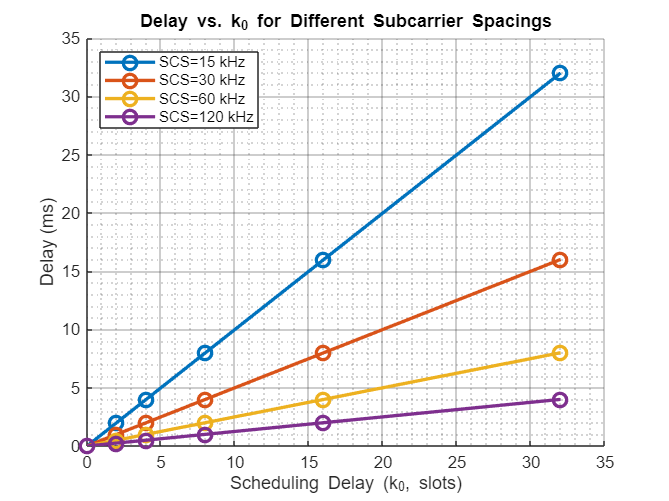

k0_values = [0, 2, 4, 8, 16, 32];
    scs_values = [15, 30, 60, 120]; % kHz
    colors = lines(length(scs_values));
    
    figure;
    hold on;
    grid on;
    
    % Oblicz i wykreśl opóźnienia dla każdego SCS
    for i = 1:length(scs_values)
        scs = scs_values(i);
        slot_duration = 1 / (scs / 15); % Długość slotu w ms
        delays_ms = k0_values * slot_duration;
        
        plot(k0_values, delays_ms, '-o', ...
             'LineWidth', 2, ...
             'MarkerSize', 8, ...
             'Color', colors(i,:), ...
             'DisplayName', sprintf('SCS=%d kHz', scs));
    end
    
    % Formatowanie wykresu
    xlabel('Scheduling Delay (k_0, slots)');
    ylabel('Delay (ms)');
    title('Delay vs. k_0 for Different Subcarrier Spacings');
    legend('Location', 'northwest');
    
    % Dodatkowe linie siatki
    set(gca, 'XMinorGrid', 'on', 'YMinorGrid', 'on', 'GridAlpha', 0.3);
    
    % Adnotacja wyjaśniająca
    text(0.8, 0.9*max(ylim), 'Delay = k_0 × slot duration', ...
         'Units', 'normalized', 'HorizontalAlignment', 'left');
    
    hold off;